# Esercizio 2

Dato il sistema descritto dalla seguente funzione di trasferimento:


$$G\left(s\right)=\frac{1}{s^2 +10s+20}$$


progettare un controllore dinamico in grado di garantire:

- errore alla rampa di pendenza unitaria inferiore al 10%

- Sovra-elongazione percentuale massima pari al 25% e tempo di assestamento minore di 2 sec

clc
clear
close all

s=tf('s');
Gs = 1/(s^2+10*s+20)

Gs =
 
         1
  ---------------
  s^2 + 10 s + 20
 
Continuous-time transfer function.
Model Properties


pole(Gs)

ans =    -7.2361
   -2.7639


La funzione di trasferimento è di tipo 0, non ha poli nell'origine, pertanto considerando la specifica richiesta al passo 1 ipotizzo un segnale di controllo $C\left(s\right)$ pari a $\frac{K}{s}$.

K deve essere scelto in modo da soddisfare le specifiche riguardanti l'errore a regime della risposta alla rampa.

Considerato il seguente schema in retroazione semplificato:

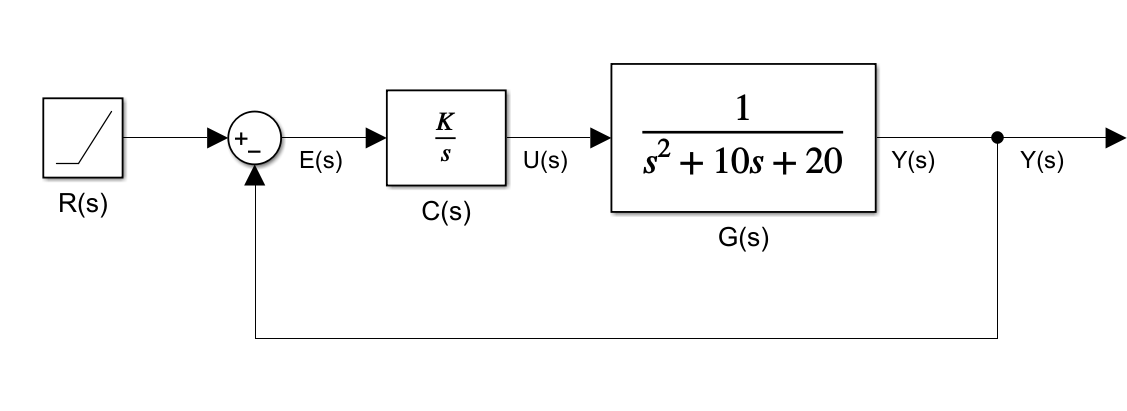

Le relazioni che legano ingressi e uscite sono:


$$L\left(s\right)=C\left(s\right)\;G\left(s\right)$$
    
$$S\left(s\right)=\frac{1}{1+L\left(s\right)}$$
    
$$E\left(s\right)=S\left(s\right)\;R\left(s\right)$$


K è scelto in modo tale che:


$$e_{\infty } =\lim_{s\to 0} \;s\;E\left(s\right)=s\;R\left(s\right)S\left(s\right)=s\;\frac{1}{s^2 }\;\frac{1}{1+\frac{K}{s}G\left(s\right)}=\frac{1}{s+K\;G\left(s\right)}=\frac{1}{K\;G\left(0\right)}=\frac{1}{\frac{K}{20}}\le 0,1$$


ovvero $K\ge 200$

Scelgo quindi $K=200,5$

K=200.5;
Cs = K/s;

Ls = Cs*Gs

Ls =
 
         200.5
  -------------------
  s^3 + 10 s^2 + 20 s
 
Continuous-time transfer function.
Model Properties


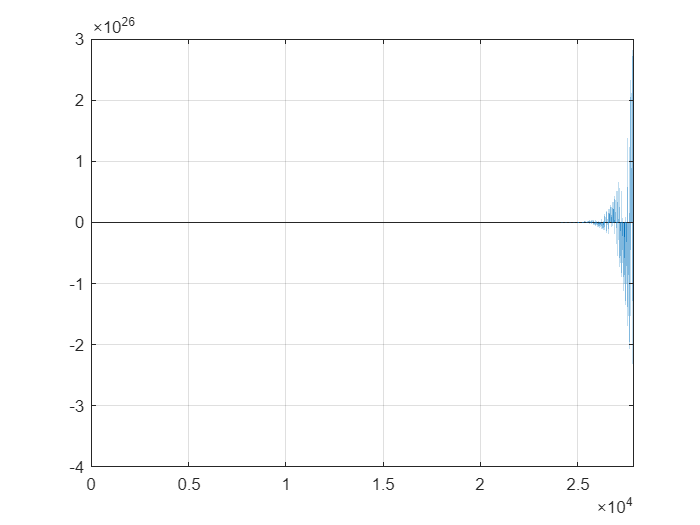


[y,t] = step((1/s)*feedback(Ls,1));
r=t;

et = (r-y)*100;
figure(1)
bar(t,et)
grid

Come si può notare dal grafico il sistema a ciclo chiuso risulta instabile. Sarà quindi necessario verificare la precisione statica a valle dell'introduzione del controllore dinamico.

Dalla specifica al punto 2 sulla sovraelongazione ricavo il fattore di smorzamento desiderato pari a $\delta=\frac{1}{\sqrt{1+\left(\frac{\pi}{\log(S)}\right)^2}}$

S = 0.23; %lascio un certo margine per sicurezza
d = 1/sqrt(1+(pi/log(S))^2) % fattore di smorzamento desiderato

d = 0.4237

Avendo il fattore di smorzamento posso ricavare la pulsazione desiderata come:

phi_m = 100*d %margine di fase desiderato

phi_m = 42.3737

Dalla specifica del tempo di assestamento che scelgo pari a  $t_s =1,8<2$ posso ricavare $\omega_n$


$$t_s =\frac{3}{\delta \omega_n }\;\to \;\omega_n =\frac{3}{t_s \delta }$$


omega_n=3/((1.9)*d)

omega_n = 3.7262

Da $\omega_n$ ricavo la banda passante come $\omega_{\textrm{bn}} =\omega_n \;f\left(\delta \right)$ con $f\left(\delta \right)=\sqrt{\left(1-2\delta^2 \right)+\sqrt{4\delta^3 -4\delta^2 +2}}$

omega_bn=omega_n*sqrt((1-2*d^2)+sqrt((4*d^3)-(4*d^2)+2)) %banda passante desiderata

omega_bn = 5.1367

Se impongo che $\hat{\omega_c } >5,14$ allora la banda passanta sarà sempre maggiore di questo valore.

Scelgo $\hat{\omega_c } =9$:

omega_c=9

omega_c = 9

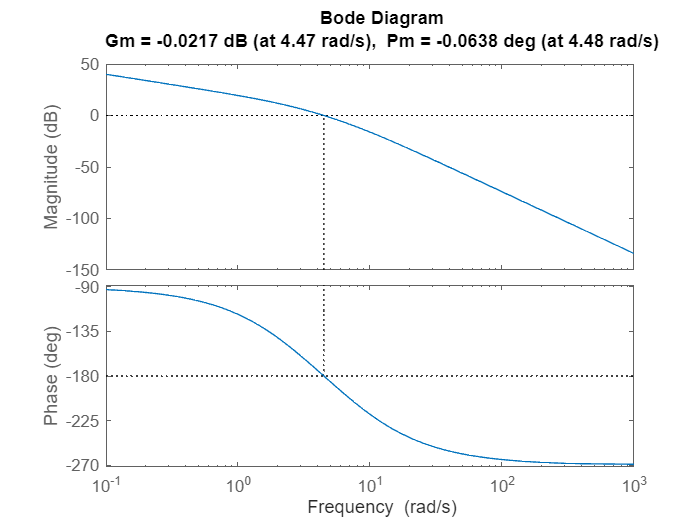

margin(Ls)

[M,phi] =bode(Ls,omega_c)

M = 0.2049

phi = -214.1285

phi_corrente = 180-abs(phi)

phi_corrente = -34.1285

Calcoliamo l'anticipo di fase necessario per ottenere il margine di fase desiderato

theta=phi_m-phi_corrente

theta = 76.5023

Pertanto siamo nello scenario in cui bisogna progettare una rete anticipatrice del tipo $C_{lead}(s)=\frac{1+sT}{1+s\alpha T}$. Imponiamo un'amplificazione $m$ pari

m = 1/M

m = 4.8804

Applichiamo la formule per il calcolo di $\alpha$ e $T$

alpha = (m*cos(deg2rad(theta))-1)/(m*(m-cos(deg2rad(theta))))

alpha = 0.0061

T = (1/omega_c)*sqrt((1-m^2)/(alpha^2*m^2-1))

T = 0.5310

Passiamo alla sintesi del controllore

Clead = (1+s*T)/(1+s*alpha*T)

Clead =
 
   0.531 s + 1
  --------------
  0.003257 s + 1
 
Continuous-time transfer function.
Model Properties


Ls = Clead*Ls

Ls =
 
                106.5 s + 200.5
  -------------------------------------------
  0.003257 s^4 + 1.033 s^3 + 10.07 s^2 + 20 s
 
Continuous-time transfer function.
Model Properties


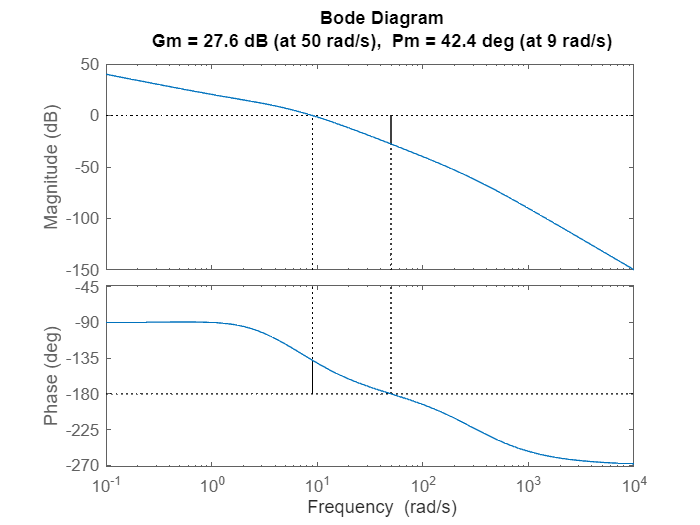

margin(Ls)

Fs = feedback(Ls,1)

Fs =
 
                     106.5 s + 200.5
  ------------------------------------------------------
  0.003257 s^4 + 1.033 s^3 + 10.07 s^2 + 126.5 s + 200.5
 
Continuous-time transfer function.
Model Properties


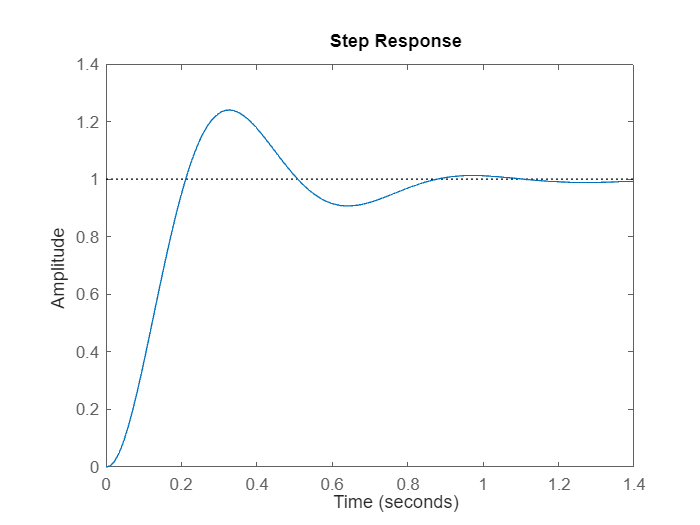

step(Fs)

stepinfo(Fs)

ans = struct with fields:
         RiseTime: 0.1408
    TransientTime: 0.8237
     SettlingTime: 0.8237
      SettlingMin: 0.9069
      SettlingMax: 1.2402
        Overshoot: 24.0237
       Undershoot: 0
             Peak: 1.2402
         PeakTime: 0.3285


Il sistema rispetta le specifiche riguardo la precisione dinamica.

Controllo nuovamente le specifiche sull'errore alla rampa:

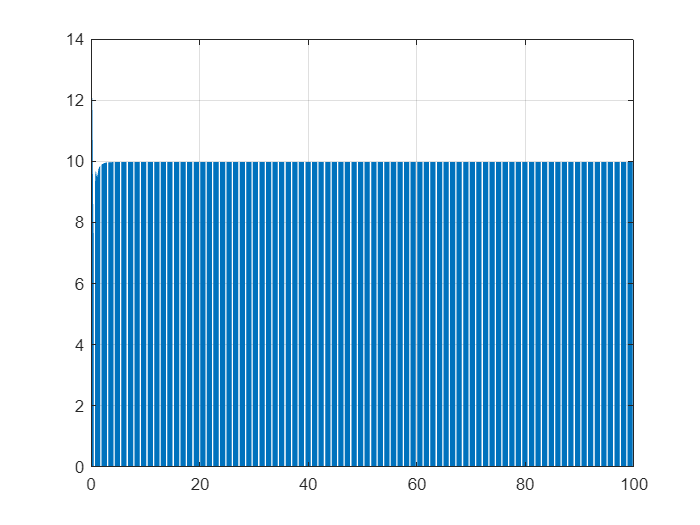

[y,t] = step((1/s)*feedback(Ls,1));
r=t;

et = (r-y)*100;
figure(1)
bar(t,et)
grid
xlim([0, 100])

Anche le specifiche sulla precisione statica sono rispettate.